% cut and align the neural activity based on task event written by NY

clear all;
close all;
clc;


Animal = 'tph209';%'tph314'; %'tph199';'tph209'
Date = '20230828'; %'20240414'; % '20230602';'20230827'
totalTrial = 150;
Key = 'roving10s'; %'roving'; %'heavy90';'roving25s'
cellset_num = 5; %3; %5; % num of session in all sessions % start from 0
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
layer_bounds_um = [263; 492; 582] %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the

layer_bounds_um =    263
   492
   582


%     Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
% Define the folder where the CSV files are located
pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/tph314_roving/20240414_tph314/output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
image_reverse = 1; %2; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/SSD-SCTU3A/Nao_behavior/202403'  filesep Date '_' Animal '_' Key]; % from 24/6
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/240718/'];

% plot event triggered neural activity
force_thr = 50; 
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 5; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 4:z scored by compared trials

load([data_folder filesep Animal '_behavior_' Date '_' Key '.mat']);

% neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
if contains(Key,'roving')
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
elseif contains(Key,'switching')
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_switching_0.5.csv']);    
else
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
end
% all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
%%% have to return the line below %%%
global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

% %%% Temporal use
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);
% acc_neural_activity_data = neural_activity_data; % temporal use
% acc_neural_property_data = neural_property_data; % temporal use

% sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))
% strcmp(neural_property_table(:,'Status'),'accepted')

% save table as mat file
save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');

acc_neural_activity_data

acc_neural_activity_data =    25.2240   -3.8027    1.9279   11.4500   18.3072   -1.3805    4.1796    9.5795   24.3012    3.8625   -3.6518   55.0633    3.9255    4.2003   20.1012   10.2303    1.9521    1.9238   33.6008    3.3186    2.7212    6.9700    4.9020   -1.3821   34.5820    6.2257   -7.3771   33.2550   -0.1592    1.1547   -1.0922    4.6453   16.0583   -2.0049   11.9585    4.1198   -1.2956   12.6770    7.3276    7.5843   -6.8790    1.4233   -0.7433   -5.7777    5.2990    2.9068    0.6362    2.8493   10.8721   38.8591
   23.3055   -1.0492    0.0230   11.2835   18.9409   -3.2420    3.1696   10.5531   23.8024    1.1513   -3.4070   55.7565    3.1299    1.4120   17.8018   11.0021   -0.2518    5.6309   33.1657    1.1771    2.1087    9.7158    6.3899   -2.5822   34.4247    5.9586   -4.5144   35.1370    0.2310    0.4629   -2.3958    6.0623   16.6455   -2.9188   11.0719    3.8559   -3.8483   11.2679    6.1176    6.7041   -7.3783    1.9932   -1.5084   -4.4966    5.8235    2.5380    2.3133  

acc_neural_property_data

acc_neural_property_data =   255.0000  255.0000  255.0000  116.0000   19.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  106.0000   52.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  114.0000   48.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  124.0000   51.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  118.0000   54.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000   96.0000   28.0000    1.0000    8.2462    1.0000
  255.0000  255.0000  255.0000  127.0000   44.0000    1.0000    8.0623    1.0000
  255.0000  255.0000  255.0000  111.0000   68.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  105.0000   42.0000    1.0000    7.2111    1.0000
  255.0000  255.0000  255.0000  101.0000   61.0000    1.0000    8.0623    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% plot neural activity
% addpath([working_directory 'PCA_and_ICA\Subaxis']);
ylimit=[0 50];
mean_acc_neural_activity = mean(acc_neural_activity_data,2);
figure
% for i = 1:size(acc_neural_activity_data,2)
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:size(acc_neural_activity_data,2)
        hold on 
        r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
        hold off
    end
    alpha(r,0.1);

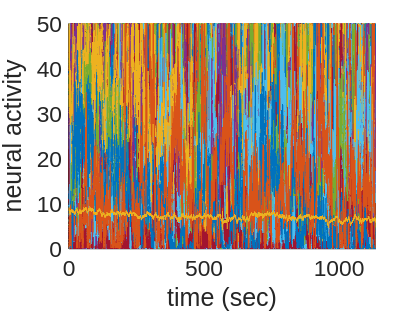

    hold on
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    ylabel('neural activity');
    xlabel('time (sec)')


% end
% saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

% plot neural activity heatmap
climit = [0 50]

climit =      0    50


figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = transpose(acc_neural_activity_data)

image =    25.2240   23.3055   21.5570   22.0273   23.0120   21.6389   23.7856   21.1366   21.0792   22.5801   20.1745   21.8004   19.3264   20.3422   19.6000   19.5326   18.2592   19.4984   18.1820   18.1838   19.7162   17.7462   19.2213   18.7412   16.7213   15.9872   17.3737   17.9424   17.7575   16.4355   16.5287   15.9186   15.0804   14.9940   15.9188   16.0188   14.5154   14.9895   15.2653   16.2753   15.6268   15.1436   16.8257   17.4434   15.3097   13.9478   14.3487   14.0023   13.7392   14.0784
   -3.8027   -1.0492   -1.1532   -0.5872   -1.6805   -1.1964   -2.3217   -1.1152   -0.6981   -0.0728   -2.0714   -1.8303   -1.0707   -2.0057   -3.0033   -0.5174    0.1983   -0.2723   -0.5516   -1.5801   -1.7534   -2.4281    0.1607   -1.1264   -0.3244   -0.0540    0.1919   -1.7409   -2.9569   -1.1062   -3.0698   -0.3365   -3.1597   -2.8689   -0.8537   -3.1130   -3.7150   -2.7795   -4.1689   -2.9851   -3.9735   -3.2251   -2.5124   -2.4610   -0.3576   -2.2470    0.0447   -2.8315   -0.4832 

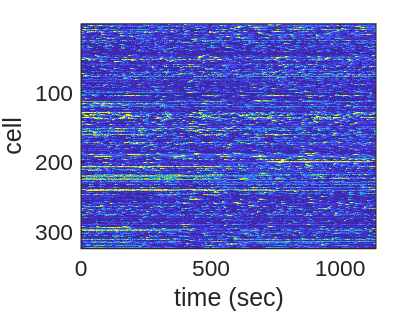

%     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(0:0.1:(size(acc_neural_activity_data,1)-1)/10,1:size(acc_neural_activity_data,2),image,clims);
%     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
% end

filename = [output_dir Date '_' Animal, '_all_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

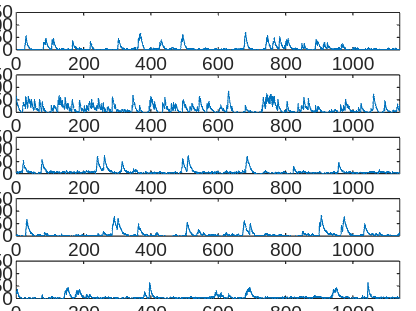

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150];
figure
for i = 1:example_num
    subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    xlim([0 (size(acc_neural_activity_data,1)-1)/10])
%     ylabel('neural activity');
%     xlabel('time (sec)')
end
filename = [output_dir Date '_'  Animal, '_exmple_activity_traces.png'];
saveas(gcf,filename);

0:0.1:(size(acc_neural_activity_data,2)-1)/10

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


% plot example neural activity with behaviors
addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150]

ylimit =      0   150


range_max =1000;
figure
for i = 1:example_num
    subaxis(example_num+3,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data(1:range_max,display_start+i));
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    xlim([0 (range_max-1)/10])
%     ylabel('neural activity');
%     xlabel('time (sec)')
end

for i = 1:3
    subaxis(example_num+3,1,i+example_num, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)))
    b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim([-0.2 1.2]); 
    xlim([0 (range_max-1)/10]);
%     ylabel('neural activity');
%     xlabel('time (sec)')
end

normalized_behavior =     0.9729    0.9729    0.9729    0.9729    0.9737    0.9738    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9736    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9729    0.9736    0.9722    0.9729    0.9729    0.9729    0.9722    0.9723    0.9729    0.9722    0.9729    0.9737    0.9729    0.9729    0.9722    0.9736    0.9729    0.9729    0.9729    0.9729    0.9736    0.9729    0.9737    0.9737


normalized_behavior =     0.1522    0.1549    0.1407    0.1057    0.1302    0.1265    0.1201    0.1382    0.1366    0.1401    0.1125    0.1082    0.0498    0.2325    0.0772    0.1207    0.1321    0.1343    0.1406    0.1425    0.1450    0.1488    0.1495    0.1404    0.1303    0.1233    0.1467    0.1446    0.1492    0.1498    0.1521    0.1559    0.1545    0.1528    0.1546    0.1579    0.1539    0.1589    0.1535    0.1549    0.1408    0.1143    0.0987    0.1332    0.1406    0.1404    0.1518    0.1501    0.1255    0.1406


normalized_behavior =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


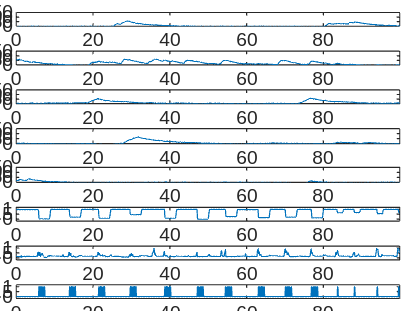

filename = [output_dir Date '_'  Animal, '_exmple_activity_behavior_traces.png'];
saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
if categorize == 'depth'
    if image_reverse == 0
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    elseif image_reverse == 2
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4); 
    else
        depth = acc_neural_property_data(:,4)*1050/(1280/4);
%     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    end
end

% determine which layer each cell belong by cell position
if categorize == 'layer'
%     layer_bounds_um = [140;250;260]; %[left, center,right] of the
%     Inscopix imaging FOV
    layer_bounds_pix = layer_bounds_um * (1280/4) /1050; 
    layer_bounds_len = length(layer_bounds_pix);
    x_pix = linspace(1, 200, layer_bounds_len);
    % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
    % TODO: have to be reverse y axis and x axis depending on the orientation of
    % the image
    if image_reverse == 0
        neural_locations = [acc_neural_property_data(:,5), acc_neural_property_data(:,4)];
    elseif image_reverse == 2
        neural_locations = [800/4 - acc_neural_property_data(:,5), 1280/4 - acc_neural_property_data(:,4)];        
    else
        % % reverse layer_bounds_pix
        % layer_bounds_pix = flip(layer_bounds_pix);
        neural_locations = [800/4 - acc_neural_property_data(:,5), acc_neural_property_data(:,4)];       
    end
    %reshape neural_locations to N*2
    % combine x_pix and layer_bounds_pix to 3*2
    linePoints = [x_pix(:), layer_bounds_pix(:)];
    % determine the layer each cell belong based on the matlab function
    % 0: layer2/3, 1: layer5
    pointAreas = classifyPoints(neural_locations, linePoints);
    % save table as mat file
    save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'pointAreas', '-append');
end

layer_bounds_pix =    80.1524
  149.9429
  177.3714


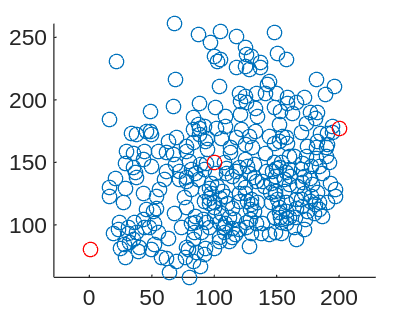

if categorize == 'layer'
    layer_bounds_pix
    close all
    figure;
    scatter(neural_locations(:,1),neural_locations(:,2));
    hold on;
    scatter(linePoints(:,1),linePoints(:,2),[],"red");
    axis equal;
    % plot().show
end

% 'behavior_neural_time'
trial_start = behavior_neural_time(:,3);
trial_end   = behavior_neural_time(:,4);
position    = behavior_neural_time(:,6);
force       = behavior_neural_time(:,7);
reward      = behavior_neural_time(:,8);
% find index of each event
trial_start_idx = find(trial_start == 1);
trial_end_idx   = find(trial_end == 1);
force_idx       = find(force > force_thr);
reward_idx      = find(reward == 1); 
position_diff   = diff(position);
position_idx    = find(position_diff > position_thr);
% idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
% event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
trial_start_act = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
trial_end_act   = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
position_act    = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
force_act       = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
reward_act      = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
sig_cell_idxs   = cell(0,5);

% only count first idx in 1 second
temp_position_idx = position_idx(1);
for i = 2:length(position_idx)
    if position_idx(i) - temp_position_idx(end) >= fps
        temp_position_idx(end+1) = position_idx(i);
    end
end
position_idx = temp_position_idx;

temp_force_idx = force_idx(1);
for i = 2:length(force_idx)
    if force_idx(i) - temp_force_idx(end) >= fps
        temp_force_idx(end+1) = force_idx(i);
    end
end
force_idx = temp_force_idx;

temp_reward_idx = reward_idx(1);
for i = 2:length(reward_idx)
    if reward_idx(i) - temp_reward_idx(end) >= fps
        temp_reward_idx(end+1) = reward_idx(i);
    end
end
reward_idx = temp_reward_idx;

% for i = 1:size(idxs,2)
%     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
exception_count = 0;
trial_start_acts = {};
for j = 1:length(trial_start_idx)
    if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_start_act = trial_start_act+transpose(acc_neural_activity_data(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
        trial_start_acts{end+1}= transpose(acc_neural_activity_data(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
    end
end
trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
if norm == 1
    trial_start_act = normalize_rows(trial_start_act);
elseif norm ==2 || norm ==4
       trial_start_act = zscore_rows(trial_start_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{1} = sig_cell_idx;
    end
    trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
end
[M,start_I] = max(trial_start_act,[],2);
trial_start_act = cat(2,start_I,trial_start_act);
trial_start_act = sortrows(trial_start_act);
trial_start_act_max_act_times = trial_start_act(:,1)/10 -2;
trial_start_act(:,1) = [];

exception_count = 0;
trial_end_acts = {};
for j = 1:length(trial_end_idx)
    if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_end_act = trial_end_act+transpose(acc_neural_activity_data(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
        trial_end_acts{end+1}= transpose(acc_neural_activity_data(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
    end
end
trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
if norm == 1
    trial_end_act = normalize_rows(trial_end_act);
elseif norm ==2 || norm == 4
   trial_end_act = zscore_rows(trial_end_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{2} = sig_cell_idx;
    end
    trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
end
[M,end_I] = max(trial_end_act,[],2);
trial_end_act = cat(2,end_I,trial_end_act);
trial_end_act = sortrows(trial_end_act);
trial_end_act_max_act_times = trial_end_act(:,1)/10 -2;
trial_end_act(:,1) = [];

exception_count = 0;
position_acts = {};
for j = 1:length(position_idx)
    if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        position_act = position_act+transpose(acc_neural_activity_data(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
        position_acts{end+1}= transpose(acc_neural_activity_data(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
    end
end
position_act = position_act/(length(force_idx)-exception_count);
position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data, 2) size(position_act,2) length(position_idx)-exception_count]);
if norm == 1
    position_act = normalize_rows(position_act);
elseif norm ==2 || norm == 4
       position_act = zscore_rows(position_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_position_acts = position_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{3} = sig_cell_idx;
    end
    position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
end
[M,pos_I] = max(position_act,[],2);
position_act = cat(2,pos_I,position_act);
position_act = sortrows(position_act);
position_act_max_act_times = position_act(:,1)/10 -2;
position_act(:,1) = [];

exception_count = 0;
force_acts = {};
for j = 1:length(force_idx)
    if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        force_act = force_act+transpose(acc_neural_activity_data(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
        force_acts{end+1}= transpose(acc_neural_activity_data(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
    end
end
force_act = force_act/(length(force_idx)-exception_count);
force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
if norm == 1
    force_act = normalize_rows(force_act);
elseif norm ==2 || norm ==4
       force_act = zscore_rows(force_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_force_acts = force_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal'); %temporal,'Alpha',0.001
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{4} = sig_cell_idx;
    end
    force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
end
[M,force_I] = max(force_act,[],2);
force_act = cat(2,force_I,force_act);
force_act = sortrows(force_act);
force_act_max_act_times = force_act(:,1)/10 -2;
force_act(:,1) = [];

exception_count = 0;
reward_acts = {};
for j = 1:length(reward_idx)
    if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        reward_act = reward_act+transpose(acc_neural_activity_data(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
        reward_acts{end+1}= transpose(acc_neural_activity_data(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
    end
end
reward_act = reward_act/(length(reward_idx)-exception_count);
reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data, 2) size(reward_act,2) length(reward_idx)-exception_count]);
if norm == 1
    reward_act = normalize_rows(reward_act);
elseif norm ==2 || norm == 4
   reward_act = zscore_rows(reward_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_reward_acts = reward_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{5} = sig_cell_idx;
    end
    reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
end
[M,reward_I] = max(reward_act,[],2);
reward_act = cat(2,reward_I,reward_act);
reward_act = sortrows(reward_act);
reward_act_max_act_times = reward_act(:,1)/10 -2;
reward_act(:,1) = [];
% end

% save table as mat file
save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'sig_cell_idxs', '-append');

% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells));
    pull_actss = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act      = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
        exception_count = 0;
        pull_acts = {};
        pull_idx = AlinmentTimingCells{i};
        for j = 1:length(pull_idx)
            if pull_idx(j)-fps*before_event<=0 | pull_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
                exception_count = exception_count + 1;
            else
                pull_act = pull_act+transpose(acc_neural_activity_data(pull_idx(j)-fps*before_event:pull_idx(j)+fps*after_event,:)); 
                pull_acts{end+1}= transpose(acc_neural_activity_data(pull_idx(j)-fps*before_event:pull_idx(j)+fps*after_event,:));
            end
        end
        pull_act = pull_act/(length(pull_idx)-exception_count);
        pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data, 2) size(pull_act,2) length(pull_idx)-exception_count]);
        if norm == 1
            pull_act = normalize_rows(pull_act);
        elseif norm ==2 || norm == 4
           pull_act = zscore_rows(pull_act); 
        elseif norm ==3
            sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
            for i_cell = 1:size(acc_neural_activity_data, 2)
                [~,max_idx] = max(mean(pull_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
                max_pull_acts = pull_acts(i_cell,max_idx,:);
                [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(max_pull_acts),'Vartype','unequal');
                if h == 1
                    sig_cell_idx(i_cell) = 1;
                else
                    sig_cell_idx(i_cell) = 0;
                end
                pull_sig_cell_idxs{i} = sig_cell_idx;
            end
            pull_act = zscore_rows(pull_act(find(sig_cell_idx==1),:));
        end
        [M,pull_I] = max(pull_act,[],2);
        pull_act = cat(2,pull_I,pull_act);
        pull_act = sortrows(pull_act);
        pull_act_max_act_times = pull_act(:,1)/10 -2;
        pull_act(:,1) = [];
        pull_actss{i} = pull_act;
        if i == 1
            pull_Is = pull_I;
        else
            pull_Is = horzcat(pull_Is, pull_I);
        end
    end
end

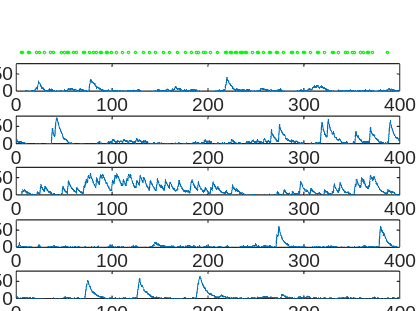

% plot example neural activity

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 60; %113;
xlimit = [0 400]; %[200 600];
ylimit = [0 80];
% threshold_value = 50; % Define your threshold value here
% force_idx = [1, 3, 12]; % Define your force_idx list

figure

% Create a common x-axis for the top plot
x_common = 0:0.1:(size(acc_neural_activity_data, 1)-1)/10;
% Create the dot plot in the second row
subaxis(example_num+1,1,1, 'Spacing', 0.01, 'Padding', 0.01, 'Margin', 0.03);
plot(force_idx/10, 0, 'go', 'MarkerSize', 1); % Adjust MarkerSize as needed
% xlim([0 (size(acc_neural_activity_data, 1)-1)/10]);
xlim(xlimit);
ylim(ylimit);
axis off; % Remove axis
hold off;

for i = 1:example_num

        % Create the subplots
        subaxis(example_num+1, 1, i+1, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
        neural_activity = acc_neural_activity_data(:, display_start+i);
        b = plot(x_common, neural_activity);
        xlim(xlimit);
        ylim(ylimit);
%     % Change x-axis labels
%     xticks([0 200 400]);
%     xticklabels({'0', '200', '400'});
end

filename = [output_dir Date '_' Animal '_exmple_activity_traces_force.png'];
saveas(gcf, filename);

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4
    climit = [-2 2];
else
    climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     2.5322    2.4987    2.5057    2.5291    2.4566    2.3529    2.3763    2.2665    2.2650    2.4724    2.3711    2.3441    2.2870    2.2094    2.2450    2.2360    2.3499    2.4184    2.0569    2.1166    1.9927    2.1830    2.1297    2.3429    2.2924    2.2579    1.9772    2.1711    2.0166    1.9880    1.8620    1.9980    1.8602    1.9379    1.7692    2.0108    1.7585    1.8177    1.6253    1.6906    1.7106    1.4885    1.5831    1.6546    1.5304    1.4819    1.4827    1.5253    1.6300    1.6453
    4.7119    4.7000    4.4722    4.5032    4.4826    4.5007    4.4680    4.4423    4.3794    4.5068    4.3471    4.4269    4.5350    4.2871    4.1256    4.0221    3.9702    3.9760    3.8495    3.7375    3.7617    3.8965    3.9298    4.1155    4.0695    4.2604    4.0674    4.1843    4.2348    4.2991    4.3793    4.2417    4.3497    4.2741    4.3986    4.2264    4.1555    4.2684    4.1870    4.0766    4.0543    3.8129    3.9043    4.0998    3.9308    3.9272    4.0248    3.9024    3.9942 

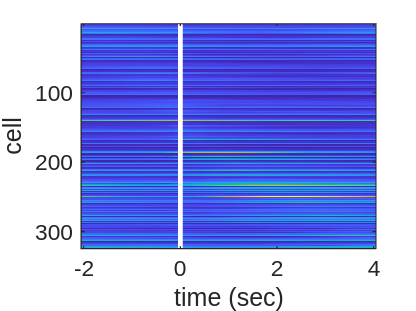

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
% end

filename = [output_dir Date '_' Animal, '_trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     2.5813    2.4686    2.5554    2.5585    2.4695    2.3331    2.2722    2.2683    2.2834    2.4888    2.3307    2.4132    2.1936    2.1913    2.2031    2.2688    2.2928    2.2787    2.1205    1.9732    2.0868    2.2460    2.2234    2.2175    2.3368    2.1522    2.1151    2.1000    1.9439    2.0394    1.8579    1.9637    1.9198    1.8504    1.7950    1.8745    1.8036    1.7043    1.6705    1.6403    1.6853    1.4518    1.6220    1.5956    1.5367    1.5440    1.4667    1.4562    1.7697    1.6192
    3.5281    3.4289    3.4291    3.4009    3.4646    3.2897    3.2424    3.1464    3.1273    3.0742    3.2143    3.1907    2.9613    3.1372    2.8488    2.8906    2.7971    2.6362    2.6615    2.9096    3.1792    3.1792    3.0101    3.0404    2.8063    2.6988    2.5363    2.4190    2.4639    2.4391    2.0256    2.1185    2.1081    1.9556    1.6039    1.5804    1.6697    1.6112    1.5276    1.5692    1.5460    1.5537    1.5354    1.5223    1.6251    1.7497    1.7741    1.7728    1.8940 

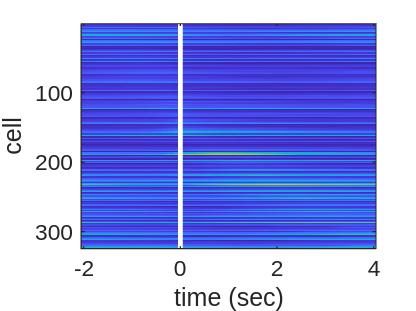

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;    
% end

filename = [output_dir Date '_' Animal, '_trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     0.4523    0.3680    0.3218    0.3467    0.3738    0.3959    0.3556    0.4031    0.3934    0.3771    0.3890    0.2727    0.0920    0.1018    0.0922    0.1253    0.1636    0.1403    0.2946    0.2748    0.2307    0.1690    0.2414    0.3130    0.2687    0.3205    0.2575    0.2474    0.2727    0.1456    0.1546    0.1398    0.0757    0.0697    0.0475    0.1133    0.1851    0.0654    0.1584    0.1671    0.2065    0.2349    0.2371    0.1612    0.2723    0.2033    0.2374    0.1419    0.2761    0.1335
    0.7244    0.6453    0.6073    0.7160    0.6556    0.5551    0.5106    0.6683    0.5686    0.5053    0.5515    0.5859    0.6271    0.5346    0.3901    0.3934    0.2818    0.2101    0.1628    0.2688    0.1670    0.1494    0.0186   -0.0326   -0.1041   -0.0922   -0.0796   -0.1579   -0.0491   -0.0522   -0.0401   -0.1135   -0.0830   -0.1155   -0.0468   -0.0456    0.0145    0.0783   -0.0514   -0.0759    0.0028    0.0516    0.0566    0.1176    0.0851    0.1764    0.1893    0.2148    0.3037 

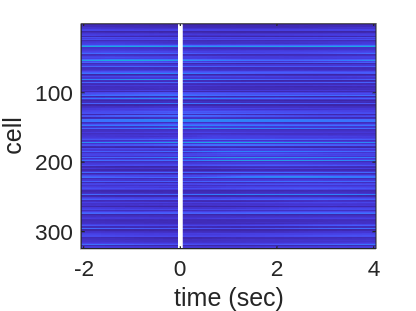

    imagesc(-before_event:0.1:after_event,1:size(position_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_position_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     3.8165    3.6907    3.7519    3.7897    3.7855    3.6856    3.7584    3.7160    3.7189    3.5828    3.6401    3.5964    3.5976    3.6817    3.7293    3.7244    3.5472    3.4770    3.5589    3.2370    3.1353    2.8111    2.8618    2.8693    2.8199    2.8501    2.6920    2.9563    2.8543    2.9755    2.6992    2.6897    2.5470    2.5569    2.6009    2.6200    2.4504    2.5335    2.5179    2.5749    2.5457    2.4766    2.4831    2.5277    2.4892    2.5917    2.6536    2.6675    2.7309    2.8060
    5.1798    4.9460    5.0140    5.0563    4.9846    5.1103    5.0213    5.1038    4.9954    5.0356    5.0874    4.9700    4.9360    4.8210    4.8361    4.7723    4.6310    4.7213    4.6073    4.5251    4.2005    4.0459    3.7728    3.7508    3.6306    3.5217    3.7054    3.6445    3.7897    3.9182    3.9501    4.0603    4.1435    3.9750    4.0181    4.1896    4.1379    4.1310    4.1894    4.4120    4.4798    4.5178    4.6590    4.5497    4.5478    4.6945    4.7234    4.7248    4.5964 

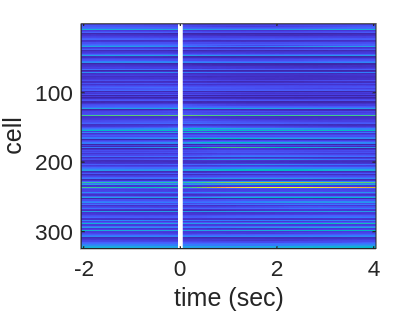

    imagesc(-before_event:0.1:after_event,1:size(force_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_force_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     2.4598    2.4393    2.4176    2.4214    2.3036    2.3632    2.2683    2.3184    2.4219    2.4338    2.3335    2.4012    2.3038    2.1028    1.9572    1.8517    1.9221    1.6815    1.6083    1.7923    1.7964    1.5125    1.6437    1.5119    1.2673    1.0919    0.9416    1.1668    0.9177    0.8907    0.8632    1.1005    0.9804    1.1261    1.0546    1.2430    0.9713    0.9812    1.3050    1.2256    1.3051    1.3006    1.4000    1.4514    1.6587    1.6796    1.7456    1.7313    1.8061    1.8183
    3.1075    3.0808    3.0803    2.9648    2.9561    2.9780    2.9982    2.9342    2.9545    2.8427    2.9271    2.7102    2.6147    2.4443    2.2591    2.1142    2.0830    1.7671    1.7903    1.6901    1.6914    1.5482    1.3893    1.3848    1.1454    0.9228    0.8731    0.9526    0.7662    0.8031    0.8218    0.8887    0.8412    0.8087    1.0189    1.0106    0.9713    0.9875    1.1267    1.0794    1.1492    1.1684    1.2103    1.3384    1.4031    1.5492    1.5456    1.7253    1.7138 

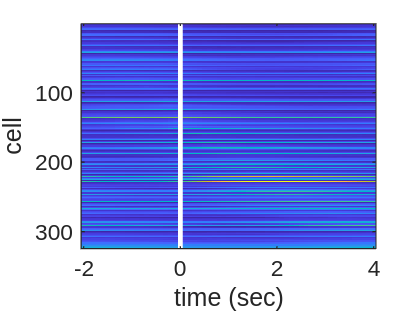

    imagesc(-before_event:0.1:after_event,1:size(reward_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_reward_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    filename = [output_dir Date '_' Animal, '_pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_actss{i}, 1);
        std_values = std(pull_actss{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
         axis tight;
    end
        
        filename = [output_dir Date '_' Animal, '_pull_eta_activity.png'];
        saveas(gcf,filename);
    % close all;
end

% write eta code by categrizing neurons by layers
if categorize == 'layer'
    layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
    layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    
    startAreas = cat(2,start_I,pointAreas);
    startAreas = sortrows(startAreas);
    startAreas(:,1) = [];
    trial_start_act_layer23_cells = trial_start_act(find(startAreas == 1),:);
    trial_start_act_layer5_cells  = trial_start_act(find(startAreas == 0),:);
    
    endAreas = cat(2,end_I,pointAreas);
    endAreas = sortrows(endAreas);
    endAreas(:,1) = [];
    trial_end_act_layer23_cells = trial_end_act(find(endAreas == 1),:);
    trial_end_act_layer5_cells  = trial_end_act(find(endAreas == 0),:);
    
    posAreas = cat(2,pos_I,pointAreas);
    posAreas = sortrows(posAreas);
    posAreas(:,1) = [];
    position_act_layer23_cells = position_act(find(posAreas == 1),:);
    position_act_layer5_cells  = position_act(find(posAreas == 0),:);
    
    forceAreas = cat(2,force_I,pointAreas);
    forceAreas = sortrows(forceAreas);
    forceAreas(:,1) = [];
    force_act_layer23_cells = force_act(find(forceAreas == 1),:);
    force_act_layer5_cells  = force_act(find(forceAreas == 0),:);
    
    rewardAreas = cat(2,reward_I,pointAreas);
    rewardAreas = sortrows(rewardAreas);
    rewardAreas(:,1) = [];
    reward_act_layer23_cells = reward_act(find(rewardAreas == 1),:);
    reward_act_layer5_cells  = reward_act(find(rewardAreas == 0),:);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if categorize == 'layer' & Kota_alignment == 1
    pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullAreass   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pullAreas = cat(2,pull_Is(i,:),pointAreas);
        pullAreas = sortrows(pullAreas);
        pullAreas(:,1) = [];
        pull_act_layer23_cells{i} = pull_actss{i}(find(pullAreas == 1),:);
        pull_act_layer5_cells{i}  = pull_actss{i}(find(pullAreas == 0),:);
        pullAreass{i} = pullAreas;
    end
end

% plot layer23 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50]
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = transpose(layer23_cells)
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer23_cells,1)-1)/10,1:size(layer23_cells,2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    
    filename = [output_dir Date '_' Animal, '_layer23_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

climit =      0    50


image =     0.8606    1.2108    3.1109    1.3983    3.4390    2.2865    1.7487    0.8370    2.2567    2.2045    0.2660    2.2163    2.7692    2.5714    1.7594    2.3874    1.2488    1.1461    0.3856   -0.4619    0.3523    0.8332   -2.0314   -1.5608    0.7592   -0.1834    2.8676   -0.0795   -1.1312   -0.4035    1.0253    1.2688    0.3488    0.7033   -0.9305    1.9399    2.2407   -0.6015    0.9894    1.5469    1.1370    1.0270   -0.3002    0.6136    0.0357    1.0734   -1.6723    0.3900   -1.4268   -1.0654
    4.9500    5.1422    3.9653    5.5669    3.7384    5.7928    6.6699    6.1078    4.3758    4.1933    5.8424    6.1234    4.2126    4.0634    4.4828    4.8734    3.5379    5.5010    4.3669    4.1909    3.4196    4.0345    4.6812    4.0057    4.3959    3.9461    5.5994    3.9661    5.0506    4.7502    5.0267    4.4176    5.0027    4.7215    4.2071    5.7765    3.7174    4.4681    3.8590    4.8107    6.5995    5.1969    6.1629    5.4971    5.9831    4.7363    3.9477    3.6557    3.3896 

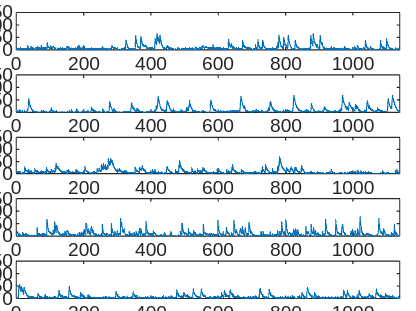

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 5;
    display_start = 1; %113;
    ylimit=[0 150];
    figure
    for i = 1:example_num
        subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
        b = plot(0:0.1:(size(layer23_cells,1)-1)/10,layer23_cells(:,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (size(layer23_cells,1)-1)/10])
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
    filename = [output_dir Date '_'  Animal, '_layer23_exmple_activity_traces.png'];
    saveas(gcf,filename);
end

% plot layer5 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50]
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = transpose(layer5_cells)
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer5_cells,1)-1)/10,1:size(layer5_cells,2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    
    filename = [output_dir Date '_' Animal, '_layer5_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

climit =      0    50


image =    25.2240   23.3055   21.5570   22.0273   23.0120   21.6389   23.7856   21.1366   21.0792   22.5801   20.1745   21.8004   19.3264   20.3422   19.6000   19.5326   18.2592   19.4984   18.1820   18.1838   19.7162   17.7462   19.2213   18.7412   16.7213   15.9872   17.3737   17.9424   17.7575   16.4355   16.5287   15.9186   15.0804   14.9940   15.9188   16.0188   14.5154   14.9895   15.2653   16.2753   15.6268   15.1436   16.8257   17.4434   15.3097   13.9478   14.3487   14.0023   13.7392   14.0784
   -3.8027   -1.0492   -1.1532   -0.5872   -1.6805   -1.1964   -2.3217   -1.1152   -0.6981   -0.0728   -2.0714   -1.8303   -1.0707   -2.0057   -3.0033   -0.5174    0.1983   -0.2723   -0.5516   -1.5801   -1.7534   -2.4281    0.1607   -1.1264   -0.3244   -0.0540    0.1919   -1.7409   -2.9569   -1.1062   -3.0698   -0.3365   -3.1597   -2.8689   -0.8537   -3.1130   -3.7150   -2.7795   -4.1689   -2.9851   -3.9735   -3.2251   -2.5124   -2.4610   -0.3576   -2.2470    0.0447   -2.8315   -0.4832 

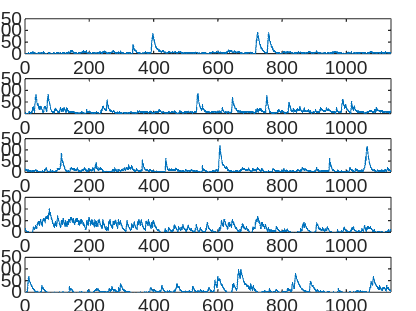

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 5;
    display_start = 1; %113;
    ylimit=[0 150];
    figure
    for i = 1:example_num
        subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.05);
        b = plot(0:0.1:(size(layer5_cells,1)-1)/10,layer5_cells(:,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (size(layer5_cells,1)-1)/10])
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
    filename = [output_dir Date '_'  Animal, '_layer5_exmple_activity_traces.png'];
    saveas(gcf,filename);
end

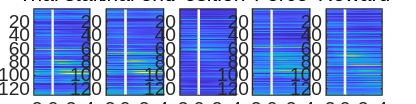

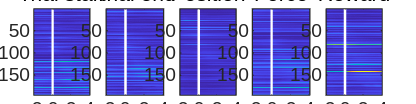

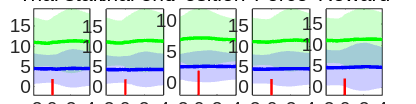

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    if norm == 1
        climit = [0 1];
    elseif norm == 2 || norm == 3 || norm == 4
        climit = [-2 2];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells};
    layer5_act  = {trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells};
    title_list = {'Trial start', 'Trial end', 'Position', 'Force', 'Reward'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;        
    end
%     xlabel('time (sec)');
   
    filename = [output_dir Date '_' Animal, '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;        
    end
%     ylabel('cell');
    filename = [output_dir Date '_' Animal, '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values23 = mean(layer23_act{i}, 1);
        std_values23 = std(layer23_act{i}, 0, 1);        
        mean_values5 = mean(layer5_act{i}, 1);
        std_values5 = std(layer5_act{i}, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;          
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_layer235_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if categorize == 'layer' & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_act_layer23_cells{i}, 1);
        std_values = std(pull_act_layer23_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;        
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_act_layer5_cells{i}, 1);
        std_values = std(pull_act_layer5_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;          
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values23 = mean(pull_act_layer23_cells{i}, 1);
        std_values23 = std(pull_act_layer23_cells{i}, 0, 1);        
        mean_values5 = mean(pull_act_layer5_cells{i}, 1);
        std_values5 = std(pull_act_layer5_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;          
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Dimention reduction using PCA, tSNE and UMAP
comp_pca = pca(transpose(zscore_rows(transpose(acc_neural_activity_data))));
comp_tsne = tsne(zscore_rows(transpose(acc_neural_activity_data)));

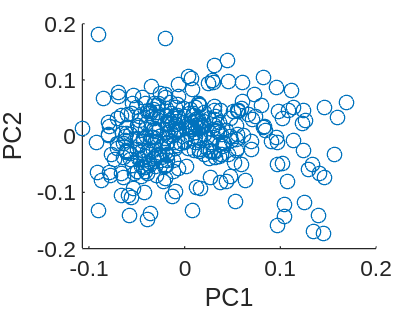

figure
scatter(comp_pca(:,1),comp_pca(:,2));
xlabel('PC1');
ylabel('PC2');

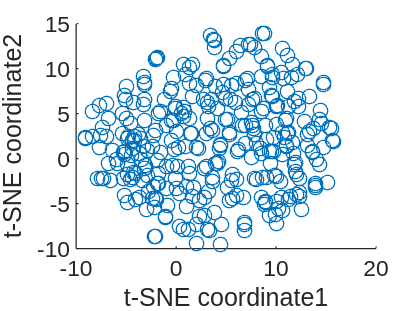

figure
scatter(comp_tsne(:,1),comp_tsne(:,2));
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');

if categorize == 'depth'
    startDepth = cat(2,start_I,depth); %(sig_cell_idxs{1}));
    startDepth = sortrows(startDepth);
    startDepth(:,1) = [];
    
    endDepth = cat(2,end_I,depth);
    endDepth = sortrows(endDepth);
    endDepth(:,1) = [];
    
    posDepth = cat(2,pos_I,depth);
    posDepth = sortrows(posDepth);
    posDepth(:,1) = [];
    
    forceDepth = cat(2,force_I,depth);
    forceDepth = sortrows(forceDepth);
    forceDepth(:,1) = [];
    
    rewardDepth = cat(2,reward_I,depth);
    rewardDepth = sortrows(rewardDepth);
    rewardDepth(:,1) = [];
end

if categorize == 'layer'
    colorcode = pointAreas;
end
if categorize == 'depth'
    colorcode = depth
end

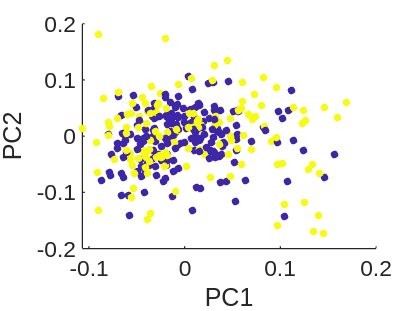

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
saveas(gcf,filename);

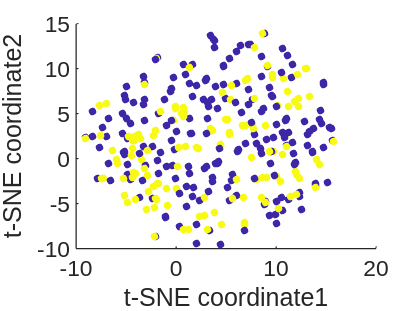

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act));
comp_tsne = tsne(trial_start_act);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

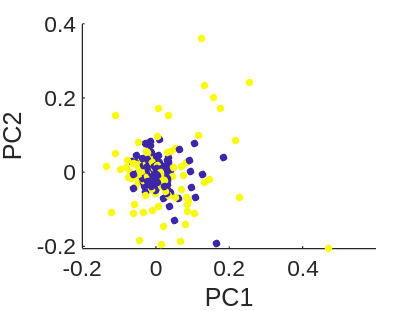

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

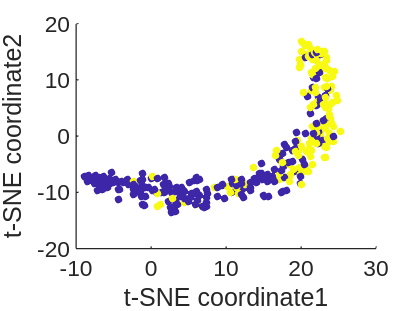

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal,'_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

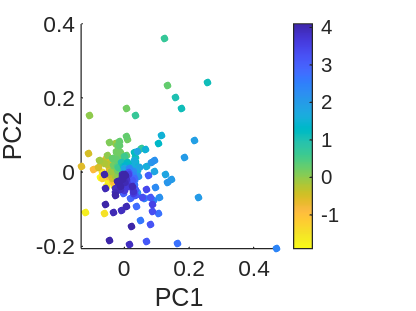

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

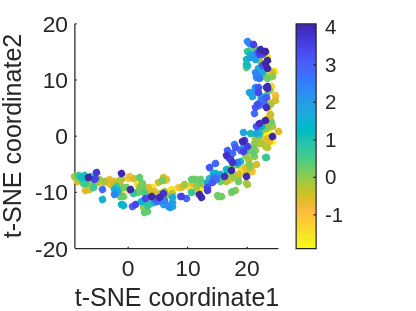

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act));
comp_tsne = tsne(trial_end_act);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

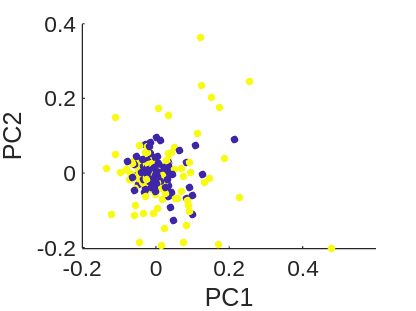

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

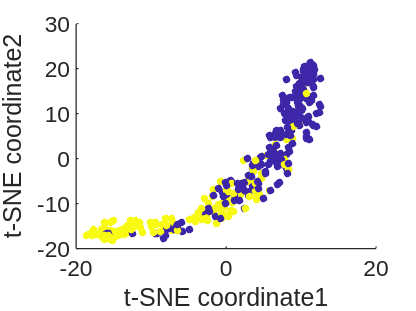

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

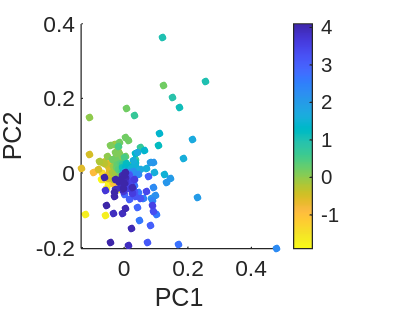

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

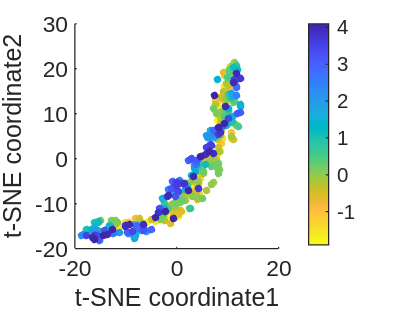

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act));
comp_tsne = tsne(position_act);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

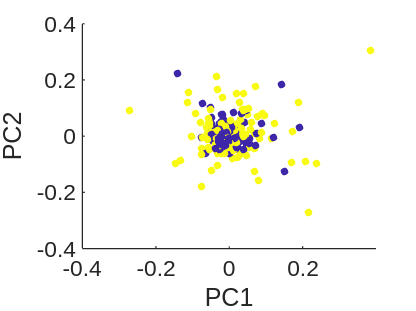

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

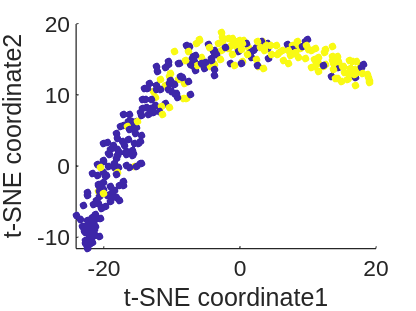

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

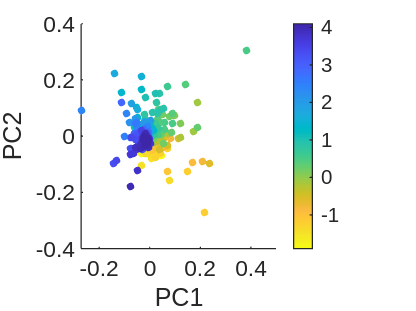

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

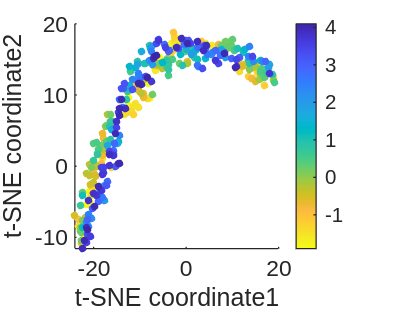

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act));
comp_tsne = tsne(force_act);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

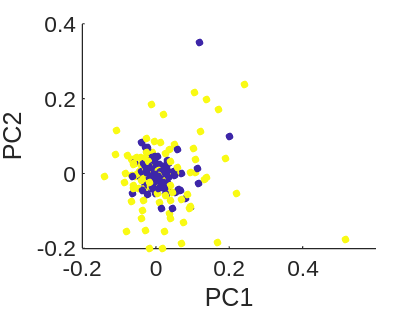

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

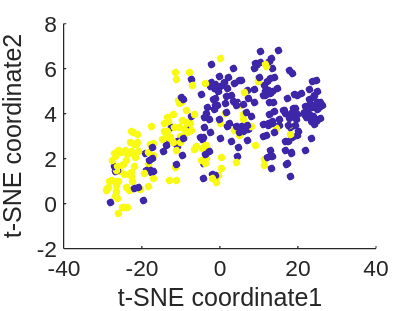

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

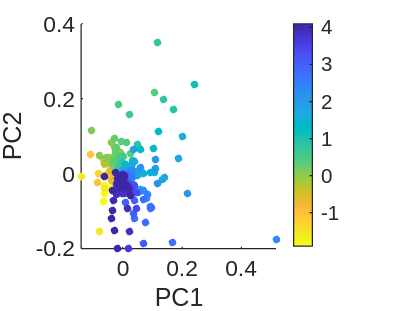

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

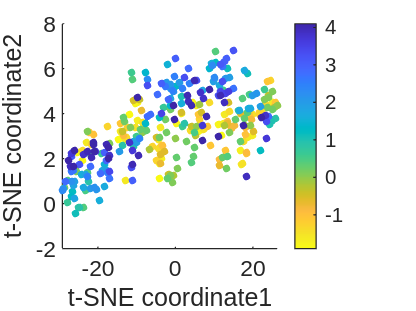

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act));
comp_tsne = tsne(reward_act);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

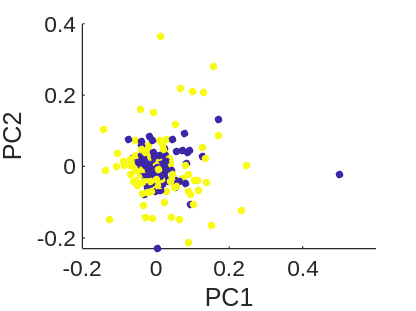

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

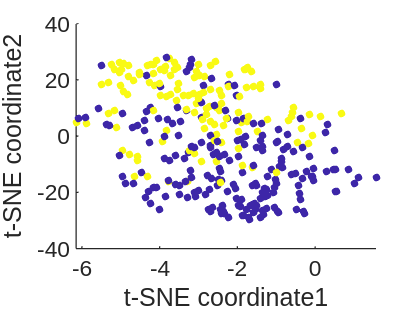

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

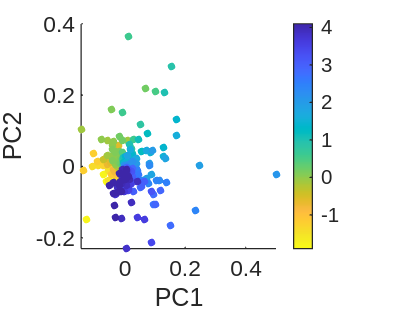

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

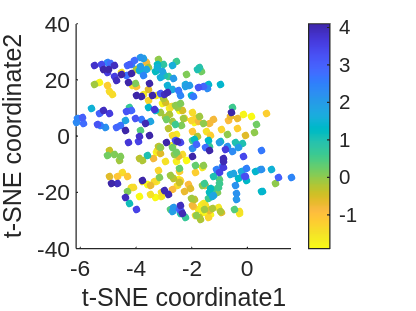

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

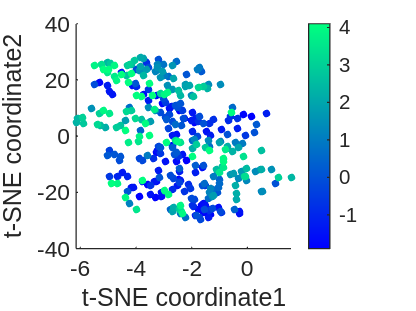

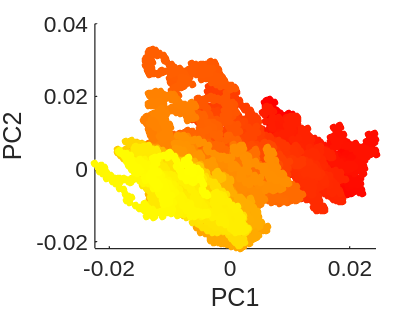

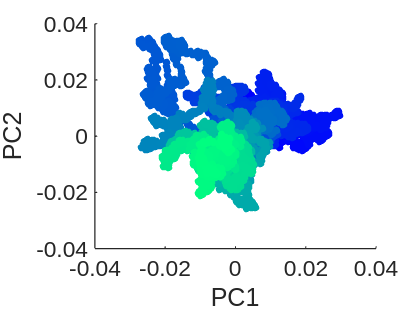

% Color hidden dimention by depth of cells
if categorize == 'layer'
    autumn = colormap('autumn');
    winter = colormap('winter');
    scaled_autumn_colors = interp1(linspace(1,size(transpose(layer23_cells),2),size(autumn,1)),autumn, 1:size(transpose(layer23_cells),2));
    scaled_winter_colors = interp1(linspace(1,size(transpose(layer5_cells),2),size(winter,1)),winter, 1:size(transpose(layer5_cells),2));
    layer23_comp_pca = pca(zscore_rows(transpose(layer23_cells)));
    layer5_comp_pca = pca(zscore_rows(transpose(layer5_cells)));
    figure
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    xlabel('PC1');
    ylabel('PC2');
    colormap(flipud(colormap));
    filename = [output_dir Date '_'  Animal, '_layer23_PCA_timecourse.png'];
    saveas(gcf,filename);

    figure
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    xlabel('PC1');
    ylabel('PC2');
    colormap(flipud(colormap));
    filename = [output_dir Date '_'  Animal, '_layer5_PCA_timecourse.png'];
    saveas(gcf,filename);
end

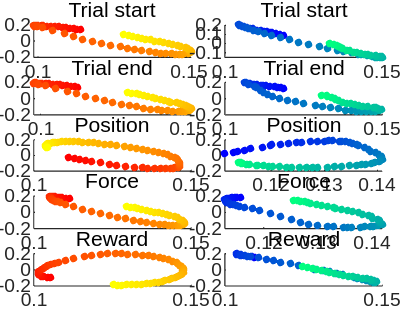

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
if categorize == 'layer'
    autumn = colormap('autumn');
    winter = colormap('winter');
    scaled_autumn_colors = interp1(linspace(1,size(layer23_act{1},2),size(autumn,1)),autumn, 1:size(layer23_act{1},2));
    scaled_winter_colors = interp1(linspace(1,size(layer23_act{1},2),size(winter,1)),winter, 1:size(layer23_act{1},2));
    figure
    for i = 1:length(layer5_act) 
        layer23_comp_pca = pca(layer23_act{i});
        layer5_comp_pca = pca(layer5_act{i});
        subaxis(length(layer5_act),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
        scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
        title(title_list{i});
        ylabel('PC2');
        if i == 5
            xlabel('PC1');
        end
        subaxis(length(layer5_act),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
        title(title_list{i});
        colormap(flipud(colormap));
        % colorbar('Direction','reverse');
        % caxis([0 1100]);
    end
    xlabel('PC1');
    filename = [output_dir Date '_'  Animal, '_' categorize '_eta_PCA_timecourse.png'];
    saveas(gcf,filename);
end

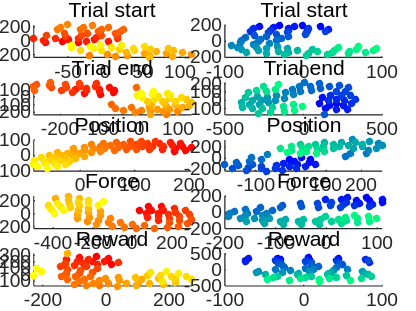

if categorize == 'layer'
    figure
    for i = 1:length(layer5_act) 
        layer23_comp_tsne = tsne(transpose(layer23_act{i}));
        layer5_comp_tsne = tsne(transpose(layer5_act{i}));
        subaxis(length(layer5_act),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
        scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
        title(title_list{i});
        ylabel('t-SNE coordinate2');
        if i == 5
            xlabel('t-SNE coordinate1');
        end
        subaxis(length(layer5_act),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
        title(title_list{i});
    %     xlabel('t-SNE coordinate1');
    %     ylabel('t-SNE coordinate2');
        colormap(flipud(colormap));
    %     colorbar('Direction','reverse');
    %     caxis([0 1100]);
    end
    xlabel('t-SNE coordinate1');
    filename = [output_dir Date '_'  Animal, '_' categorize '_eta_tSNE_timecourse.png'];
    saveas(gcf,filename);
end

% split trials and eta anlysis for detecting prediction error or action
% value
trial        = behavior_neural_time(:,2);
resistance   = behavior_neural_time(:,5);
res_all  = unique(sort(resistance));
res_high = res_all(2);
res_low  = res_all(1);
switch_inter = NaN;
if contains(Key,'heavy')
    session_type = res_high;
elseif contains(Key,'light')
    session_type = res_low;
elseif contains(Key,'roving')
    Keynum = regexp(Key,'\d+','match')
    if length(Keynum)>0
        switch_inter = str2num(Keynum{1});
    end
end

Keynum = 1×1 の cell 配列
    {'10'}


% trial_end and do not get reward (reward prediction error)
% no_reward_idx  = find(trial_end == 1);
no_reward_idx = [];
for i = 1:length(trial_end_idx)
    if any(reward_idx >= i & reward_idx < i+fps)% there is reward_idx == j
        continue;% skip for loop
    end
    no_reward_idx(end+1) = trial_end_idx(i); % no reward within 1 seconds
%     if trial_end_idx(i) reward_idx % no reward within 1 seconds
%         no_reward_idx(end+1) = trial_end_idx(i)
%     end
end
% force during trial in which session type == trial type
% force during trial in which session type != trial type (sensory prediction error)
prediction_error_idx    = [];
prediction_no_error_idx = [];
for i = 1:length(force_idx)
    if force_idx(i)+fps < length(trial)
        temp_resistance = min(resistance(force_idx(i):force_idx(i)+fps)); % expand 1 sec to include force just before trial
    else    
        temp_resistance = resistance(force_idx(i));
    end
    if ~isnan(switch_inter)
        if rem((i-1),(switch_inter*2)) <= switch_inter
            session_type = res_low;
        else
            session_type = res_high;
        end
    end

    if temp_resistance == Inf
        continue; % skip for loop
    % case of roving oddball paradigm
    elseif length(Keynum) == 0
        pre_trial_idx = max(trial_end_idx(trial_end_idx<force_idx(i)))-1;
        post_trial_idx = min(trial_start_idx(trial_start_idx>force_idx(i)))+1;
        pre_trial_resistance = resistance(pre_trial_idx);
        post_trial_resistance = resistance(post_trial_idx);
        if temp_resistance ~= pre_trial_resistance
            prediction_error_idx(end+1) = force_idx(i);
        elseif temp_resistance ~= post_trial_resistance
            prediction_no_error_idx(end+1) = force_idx(i);
        end
    elseif temp_resistance ~= session_type
        prediction_error_idx(end+1) = force_idx(i);
    elseif temp_resistance == session_type
        prediction_no_error_idx(end+1) = force_idx(i);
    end
end
% action value can only calculated in session in which reward amount is
% changed
% force during trial in which reward is high (Q:action value)
% force during trial in which reward is low
action_value_idx    = [];
action_no_value_idx = [];
for i = 1:length(force_idx)
    if force_idx(i)+fps < length(trial)
        temp_trial      = max(trial(force_idx(i):force_idx(i)+fps));
        temp_resistance = min(resistance(force_idx(i):force_idx(i)+fps)); % expand 1 sec to include force just before trial
    else
        temp_trial      = trial(force_idx(i));
        temp_resistance = resistance(force_idx(i));
    end
    if temp_resistance == Inf
        continue; % skip for loop
    elseif temp_trial <= totalTrial/2 && temp_resistance == res_high
        action_no_value_idx(end+1) = force_idx(i);
    elseif temp_trial <= totalTrial/2 && temp_resistance == res_low
        action_value_idx(end+1)    = force_idx(i);
    elseif temp_trial > totalTrial/2 && temp_resistance == res_high
        action_value_idx(end+1)    = force_idx(i);
    elseif temp_trial > totalTrial/2 && temp_resistance == res_low
        action_no_value_idx(end+1) = force_idx(i);
    end
end

eta_acts = cell(1,6);
eta_actss = cell(1,6);
eta_idxs = {no_reward_idx, reward_idx, prediction_error_idx, prediction_no_error_idx, action_value_idx, action_no_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
% eta_idxs = {reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_no_value_idx, action_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
eta_idx_idxs = [2,1,4,3,5,6];
max_acts = cell(1,6);
sig_cell_idxs2 = cell(1,6);
max_I = cell(1,6);
max_act_times = cell(1,6);

for i = 1:length(eta_acts)
    eta_acts{i} = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
    exception_count = 0;
    i_eta_acts = {};
    for j = 1:length(eta_idxs{i})
        if eta_idxs{i}(j)-fps*before_event<=0 | eta_idxs{i}(j)+fps*after_event>size(acc_neural_activity_data,1)
            exception_count = exception_count + 1;
        else
            eta_acts{i} = eta_acts{i}+transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
            i_eta_acts{end+1}= transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
        end
    end
    eta_acts{i} = eta_acts{i}/(length(eta_idxs{i})-exception_count);
    i_eta_acts = reshape(cell2mat(i_eta_acts),[size(acc_neural_activity_data, 2) size(eta_acts{i},2) length(eta_idxs{i})-exception_count]); %-1]);
    eta_actss{i} = i_eta_acts;
    if norm == 1
        eta_acts{i} = normalize_rows(eta_acts{i});
    elseif norm ==2
        eta_acts{i} = zscore_rows(eta_acts{i}); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
        for i_cell = 1:size(acc_neural_activity_data, 2)
            [~,max_idx] = max(mean(i_eta_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_acts{i} = i_eta_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal'); %temporal,'Alpha',0.001
%             [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal','Alpha',0.001); %temporal,'Alpha',0.001
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs2{i} = sig_cell_idx;
        end
        eta_acts{i} = zscore_rows(eta_acts{i}(find(sig_cell_idx==1),:));
    elseif norm == 4 % zscored no error activity by error or action value activity
        if i == 2 || i == 4 || i == 6
            eta_acts{i} = zscore_rows_by_diff_matrix(eta_acts{i},eta_old);
        else
            eta_old = eta_acts{i};
            eta_acts{i} = zscore_rows(eta_acts{i}); 
        end
    end
    [M,max_I{i}] = max(eta_acts{i},[],2);
    eta_acts{i} = cat(2,max_I{i},eta_acts{i});
    eta_acts{i} = sortrows(eta_acts{i});
    max_act_times{i} = eta_acts{i}(:,1)/10 -2;
    eta_acts{i}(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(i_eta_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);
        % 2つのテンソルに分割
        i_eta_acts_train = i_eta_acts(:, :, indices1);
        i_eta_acts_test  = i_eta_acts(:, :, indices2);
        % sort with train data
        i_eta_act_train_raw = mean(i_eta_acts_train,3);
        i_eta_act_test_raw  = mean(i_eta_acts_test,3);
        trial_len = size(i_eta_act_train_raw,2);
        [M,max_I{i}] = max(i_eta_act_train_raw,[],2);
        eta_acts{i} = cat(2,max_I{i},i_eta_act_train_raw, i_eta_act_test_raw);
        eta_acts{i} = sortrows(eta_acts{i});
        max_act_times{i} = eta_acts{i}(:,1)/10 -2;
        eta_acts{i}(:,1) = [];
        % trial_start_act_train = eta_acts{i}(:,1:trial_len);
        i_eta_act_test  = eta_acts{i}(:,trial_len+1:size(eta_acts{i},2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        eta_acts{i} = zscore_rows(i_eta_act_test);
    end    
end
eta_acts = eta_acts(eta_idx_idxs);
max_acts = max_acts(eta_idx_idxs);
max_I = max_I(eta_idx_idxs);
max_act_times = max_act_times(eta_idx_idxs);

% % check the number of action value represented cells
% sig_cell_idxs{4}; % force_idx
% sig_cell_idxs2{5}; % action_value_idx
% sig_cell_idxs2{6}; % action_no_value_idx
% all_set = sum(sig_cell_idxs{4}==1)
% and_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% value_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{5}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% no_value_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{6}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% rem_set = sum(sig_cell_idxs{4}==1) + sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{6}==2)
% action_value_cell_num = [all_set and_set value_set no_value_set rem_set];
% 
% filename = [output_dir Date '_' Animal '_action_value_cell.csv'];
% writematrix(action_value_cell_num,filename);

% write eta code by categrizing neurons by layers
eta_layer23_acts = cell(1,6);
eta_layer5_acts  = cell(1,6);
etaAreas         = cell(1,6);

if categorize == 'layer'  
    for i = 1:length(eta_acts)
        etaAreas{i} = cat(2,max_I{i},pointAreas);
        etaAreas{i} = sortrows(etaAreas{i});
        etaAreas{i}(:,1) = [];
        eta_layer23_acts{i} = eta_acts{i}(find(etaAreas{i} == 1),:);
        eta_layer5_acts{i}  = eta_acts{i}(find(etaAreas{i} == 0),:);
    end
end

image =    -0.4881    0.1135   -0.5112   -0.0745    0.3922   -0.1805    0.6927    0.0286    1.2416   -0.0618    1.4395    1.3747    1.1299    1.8487    0.6979    1.9874    0.7689    1.4826    0.5912    0.1439   -0.6785    0.2411    0.6809    0.4762    0.7208    1.0330    0.8756   -0.2296    0.8894    0.8183    0.0506    0.1615    0.1662    0.2571    0.3849    1.1478    1.2296   -0.0312   -0.2956    0.2475    0.4692    0.6313    0.1389   -0.6443   -0.4360   -0.4485   -0.0295   -1.1563   -1.0297   -1.2844
    0.8900    1.1723    2.5616    0.9620    1.2631    0.9047    0.9109    1.1400   -0.0025    1.2816    1.2571    1.3375    0.9991    1.6917    0.5433    0.7614    1.7858    1.2964   -1.4337   -2.3379   -1.5345   -0.8145   -1.4948   -0.8103   -0.5429   -1.7173   -1.2609   -1.1272   -0.7100   -0.9168   -0.4151    0.4226   -0.1534   -0.8381    0.8301    0.0242   -0.4713   -1.1027    1.2530    0.4092   -0.3897   -0.6414   -0.2015   -0.7758   -0.4600   -0.4412   -0.5444   -0.2843   -0.3727 

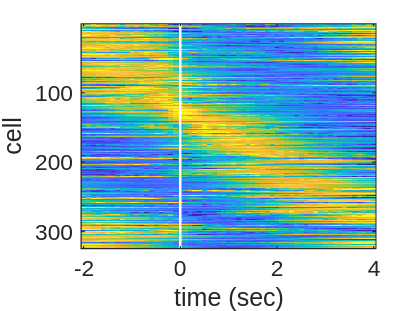

image =    -1.0550   -1.5494   -1.8976   -1.2414   -0.6951   -0.4106   -0.5865   -0.3570   -0.2660   -0.5545    0.2593    0.5242    0.6736    1.2548    1.6136    1.3529    1.2750    1.6745    2.0840    1.9931    1.1838    1.2585    0.0963    0.6596    0.2609   -0.1908   -0.2782    0.3670    0.0235   -0.4639   -0.0469   -0.8504   -0.3679   -0.6098   -1.1884   -1.2610   -1.2355   -1.8785   -0.9130   -1.3100   -0.9441   -1.4559   -0.4005   -0.6924   -0.6595   -1.2986   -0.6614   -0.5134    0.1641    0.0815
    1.6039    1.5210    1.6925    1.2979    1.7863    1.2163    1.1407    1.0217    0.9621    0.9027    1.2737    1.2726    1.0578    1.3186    0.7676    0.7594    0.6518    0.4921    0.3164    0.8015    1.3742    1.0920    1.0176    1.0880    0.6419    0.2988    0.1224   -0.2426    0.0846   -0.1347   -0.7044   -0.4869   -0.4035   -0.8123   -1.2319   -0.9296   -1.0629   -1.2442   -1.2896   -1.2884   -1.3007   -1.2545   -1.1862   -1.3805   -0.8763   -0.8216   -1.0894   -0.9741   -0.7161 

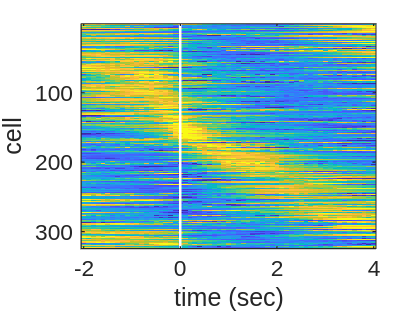

image =     1.1971    1.3001    1.0525    1.7198    1.0782    1.0974    0.9013    0.8127    0.8012    0.5290    0.5743    0.1930    0.3389    0.7715    0.9429    0.8637    1.0631    1.3376    1.8447    1.4365    2.4025    1.8629    1.2792    0.5956    0.2002   -0.3063   -0.9009   -0.8227   -0.5241    0.2248   -0.6359   -0.2242    0.5331   -0.4578   -0.2175   -0.4343   -1.6295   -0.9017   -0.7392   -0.8826   -0.5126   -0.9695   -0.7922   -0.6052   -0.5991   -0.5246   -0.8656   -0.9822   -1.3092   -1.2435
   -1.0313   -0.0410    0.9434    1.0005    0.6453    0.2156    0.9277   -0.3146    0.6288    0.6929    0.2527    1.4360    1.4996    0.8305    2.0158    1.1685    1.3405    0.2781    1.0201    1.3462    0.9224    1.3469    1.1380    1.3954    0.7748    0.7329    0.6818    0.2590    0.6456   -0.0415   -0.7544    0.1852    0.4435   -0.1583   -0.2708   -0.9639   -0.7684   -0.5101   -0.9396   -1.4589   -1.6706   -0.5604   -0.8305   -1.3994   -1.0575   -1.2954   -1.3741   -1.0056   -1.8798 

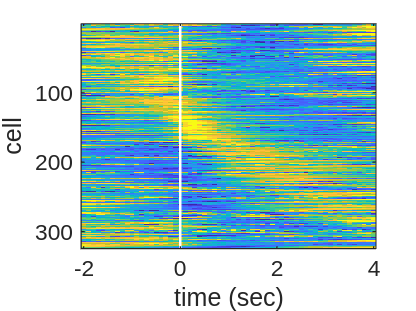

image =    -0.2112    0.0820   -0.3663   -0.5609   -0.9455   -0.5625   -0.4822   -0.7490   -0.8139   -0.4681   -0.5967   -0.7409   -0.6126   -0.3629   -1.0565   -0.8876   -0.3131   -1.0410   -1.2136   -1.2995   -0.0418   -0.4358   -0.9799   -0.7101   -1.0559   -0.7303   -0.7769   -0.7242   -1.2324   -0.1957   -0.7616   -0.5601   -1.0754   -0.2467   -0.3129   -0.4775   -0.5735   -0.6702   -0.0885   -0.8038    0.1737    0.6342    1.5590    0.5405    1.5494    1.7857    1.5894    2.1419    1.4567    1.4233
   -0.6794   -0.8867   -1.2456   -0.6700   -0.7448   -0.8762   -0.6165   -1.2096   -0.8002   -0.6352   -0.9117   -1.0980   -0.8895   -1.0091   -1.3140   -0.6766   -0.6538   -1.1449   -0.7910   -0.9705   -0.9992   -0.4342    0.2441    0.2402   -0.0129   -0.8349   -0.1458   -0.0006    0.3890    0.4403    0.6589    1.2391    1.5779    0.9191    1.1028    1.9372    2.4968    2.2592    2.2596    1.9094    1.4422    1.2292    1.0044    0.3802    0.5204    0.3225    0.9164    0.7531    0.6068 

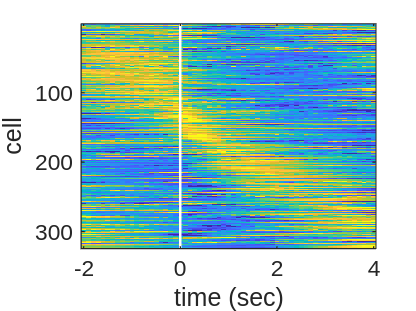

image =     1.1572    1.3622    1.5356    1.2355    1.3216    1.2669    1.6803    2.1218    1.2530    1.4088    1.2431    1.5109    1.3024    0.9048    1.2737    0.7774    0.8818    1.0482    0.4169    0.0315   -0.4067   -0.1950   -0.9463   -0.8202   -0.7088   -0.9783   -0.7681   -0.3266   -0.6540   -0.2308   -0.2000   -0.1930    0.5010    0.1174   -0.2332    0.2386    0.3274    0.1443    0.2125    0.0207   -0.2634   -0.4167   -0.5254   -0.1814   -0.8683   -0.9371   -0.9886   -1.8683   -1.7504   -1.5018
    0.0218   -0.2576   -0.2632   -0.2799   -0.1679   -0.8815   -0.2932   -1.1652   -0.1943   -0.2101    0.6490    0.0278   -1.3149   -0.0753    0.1607   -1.2444   -1.0404   -0.6575   -0.3576   -0.9099   -0.0336   -0.5886   -0.9947   -0.6190   -0.8927   -0.8078   -0.6309   -0.1173   -1.7136   -1.3906   -1.4078   -0.7624   -0.3458   -0.2752   -0.2063   -0.1468   -0.5505    0.0188   -0.4983   -0.2729   -0.4833   -0.8788   -1.0323   -0.1865    0.1235    0.7114    1.0968    1.8113    0.9867 

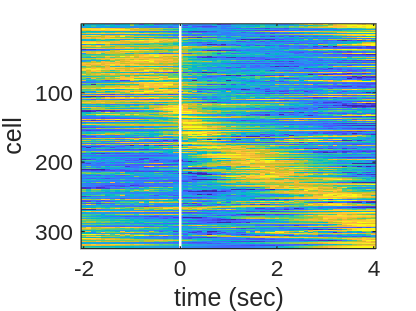

image =     0.2296    0.9121    1.0639    1.5789    1.3617    1.3751    1.4211    0.0677    1.4615    1.5169    0.3635    2.2120    0.8204    2.1233    1.7687    0.8580    0.9580    1.7073    1.1964    0.8676   -0.3073    0.3559   -0.5250   -0.0593   -0.8286   -0.2431   -0.9813   -0.9638   -0.5393   -0.7845    0.1578    0.4604   -0.3792   -0.9279    0.4775   -0.1674    0.1644   -0.1294   -0.2757   -0.6322   -0.8190   -1.1821   -1.0260   -1.3014   -0.7088   -1.3648   -0.5798   -1.1596   -0.9322   -0.9442
   -0.0330   -0.4945    0.0310   -0.3172    0.4557   -0.0176    0.2564    0.2432   -0.3604   -0.5941    0.0421    0.0118    0.7274    0.5346    0.5530    0.5145    0.6764    1.1325    1.4982    1.5738    2.1473    1.3380    1.5220    1.0776    0.4913    0.3848    1.0466    1.2396    1.1229    0.6721    0.5979    0.1903   -0.0738   -0.3980   -0.5439    0.1015    0.3793   -0.0058    0.0013    0.6643    0.3965    0.3919    0.2165   -0.0278   -0.4327    0.1091    0.2395   -0.4592   -0.5782 

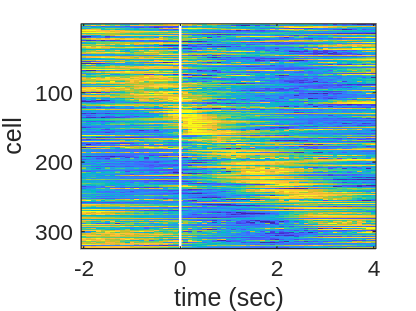

% plot neural activity heatmap
title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4 || norm == 5
    climit = [-2 2];
else
    climit = [0 20]; %[0 50];
end

for i = 1:length(eta_acts)
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = eta_acts{i} %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_acts{i},1),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
    filename = [output_dir Date '_' Animal '_' title_list{i} '_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;
end

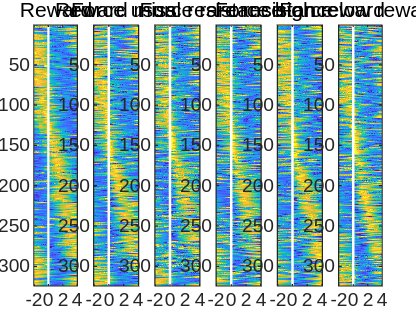

figure
set(gcf,'color','w');

for i = 1:length(eta_acts) 
    subaxis(1,length(eta_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    clims = climit;
    image = eta_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(-before_event:0.1:after_event,1:size(eta_acts{i},1),image,clims);
%         ylabel('cell');
    xlabel('time (sec)');
    if i == 1
        ylabel('cell');
    end
    title(title_list{i});
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
end
%     xlabel('time (sec)');

filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_') '_eta_activity_heatmap.png'];
saveas(gcf,filename);

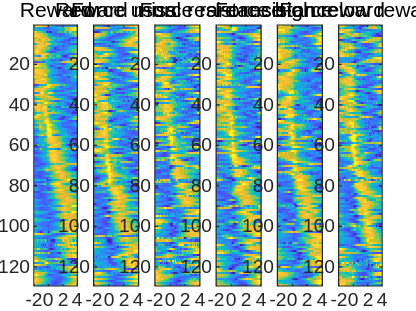

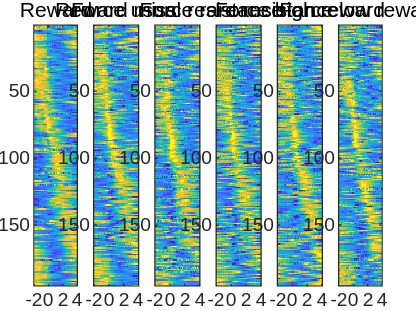

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    figure
    set(gcf,'color','w');
    for i = 1:length(eta_layer23_acts) 
        subaxis(1,length(eta_layer23_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = eta_layer23_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_layer23_acts{i},1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_') '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(eta_layer5_acts) 
        subaxis(1,length(eta_layer5_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = eta_layer5_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_layer5_acts{i},1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_')  '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% plot example neural activity
high_low_reward_idx = sig_cell_idxs2{5} & sig_cell_idxs2{6};
high_reward_idx     = sig_cell_idxs2{5} & ~sig_cell_idxs2{6};
low_reward_idx      = ~sig_cell_idxs2{5} & sig_cell_idxs2{6};
neither_idx         = ~sig_cell_idxs2{5} & ~sig_cell_idxs2{6};
example_num = 4;
categories   = {high_low_reward_idx, high_reward_idx, low_reward_idx, neither_idx};
category_str = {'high_and_low_reward','high_reward','low_reward','neither_reward'};

Force_act = mean(force_acts,3);
Force_act_high = mean(eta_actss{5},3);
Force_act_low = mean(eta_actss{6},3);

for m = 1:length(categories)
    figure
    m_category = categories{m};
    all_cell = find(m_category == 1);
    for i = 4:7 %1:example_num
        i_cell = all_cell(i);

        Force_act = squeeze(force_acts(i_cell,:,:));
        Force_act_high = squeeze(eta_actss{5}(i_cell,:,:));
        Force_act_low  = squeeze(eta_actss{6}(i_cell,:,:));
        Force_act_SEM = transpose(std(Force_act,0,2)/sqrt(size(Force_act,2)));
        Force_act_high_SEM = transpose(std(Force_act_high,0,2)/sqrt(size(Force_act_high,2)));
        Force_act_low_SEM  = transpose(std(Force_act_low,0,2)/sqrt(size(Force_act_low,2)));        
        Force_act = transpose(mean(Force_act,2));
        Force_act_high = transpose(mean(Force_act_high,2));
        Force_act_low  = transpose(mean(Force_act_low,2));        
    
        subaxis(example_num,1,i-3, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:0.1:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,Force_act,'m','LineWidth',2);
        plot(x,Force_act_high,'c','LineWidth',2);
        plot(x,Force_act_low,'g','LineWidth',2);        
        alpha_value = 0.2;
        inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
        fill(x2, inBetween1, 'm', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween2 = [Force_act_high + Force_act_high_SEM, fliplr(Force_act_high - Force_act_high_SEM)];
        fill(x2, inBetween2, 'c', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween3 = [Force_act_low + Force_act_low_SEM, fliplr(Force_act_low - Force_act_low_SEM)];
        fill(x2, inBetween3, 'g', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);        
        xline(0,'--k');
%         xline(p_time_temp_transformed(find(p_trial_end==1)),'--k');
%         title(['Force eta']);
    %         title(['R2 = ' num2str(R2)]);
        hold off;
        if i_cell ~= example_num
            set(gca,'TickLength',[0 0]);
            set(gca,'XTickLabel',[]);
        end
        if i == 4 %1
            legend({'All','High reward','Low reward'},'Location','northwest');
        end
    end
    xlabel('time');
    filename = [output_dir Date '_'  Animal '_' category_str{m} '_force_ETA.png'];
    saveas(gcf,filename);
end

インデックスが配列要素数を超えています。インデックスは 0 を超えてはなりません。

% plot pie graph
data = [sum(high_low_reward_idx) sum(high_reward_idx) sum(low_reward_idx) sum(neither_idx)];
labels = {'high and low reward','high reward','low reward', 'neither'};
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
p = pie(data); %, labels);
% title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
pText = findobj(p,'Type','text');
percentValues = get(pText,'String');
txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
combinedtxt = strcat(percentValues,txt);
pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
legend(labels,'Location','southoutside'); 

filename = [output_dir Date '_'  Animal, '_' categorize '_action_value_cells_pie.png'];
saveas(gcf,filename);

% % plot pie graph
data = [73 48 17 176];
labels = {'high and low reward','high reward','low reward', 'neither'};
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
p = pie(data); %, labels);
% title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
pText = findobj(p,'Type','text');
percentValues = get(pText,'String');
txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
combinedtxt = strcat(percentValues,txt);
pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
legend(labels,'Location','southoutside'); 

% filename = [output_dir Date '_'  Animal, '_' categorize '_action_value_cells_pie.png'];
% saveas(gcf,filename);

% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function zscored_matrix2 = zscore_rows_by_diff_matrix(matrix1, matrix2)
    zscored_matrix2 = (matrix1 - mean(matrix2, 2)) ./ std(matrix2,0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end